# Exercise 1.1

clear all;
clc;
close all;

% Setup parameters for Problem
sim_name = 'concentration_1_1';
h = 1;
N = 100;
dt = 0.00004;
numberSteps = 10000;
makeVideo = true;

dx = h/(N-1);
s = dt/dx^2;

% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
% Set boundary condition at x=0
C(1) = 1;
% Set boundary condition at x=h
%C(end) = 1;
if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

% SIMULATION
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_explicit(C,s,1);
    
    if makeVideo && mod(i,30)==0
        C_analytic = analyticalSolution(N,100,i*dt);
        writeFrame(v, C, x, i, sim_params, C_analytic)
    end
    
end

10.00 %


20.00 %


30.00 %


40.00 %


50.00 %


60.00 %


70.00 %


80.00 %


90.00 %


100.00 %


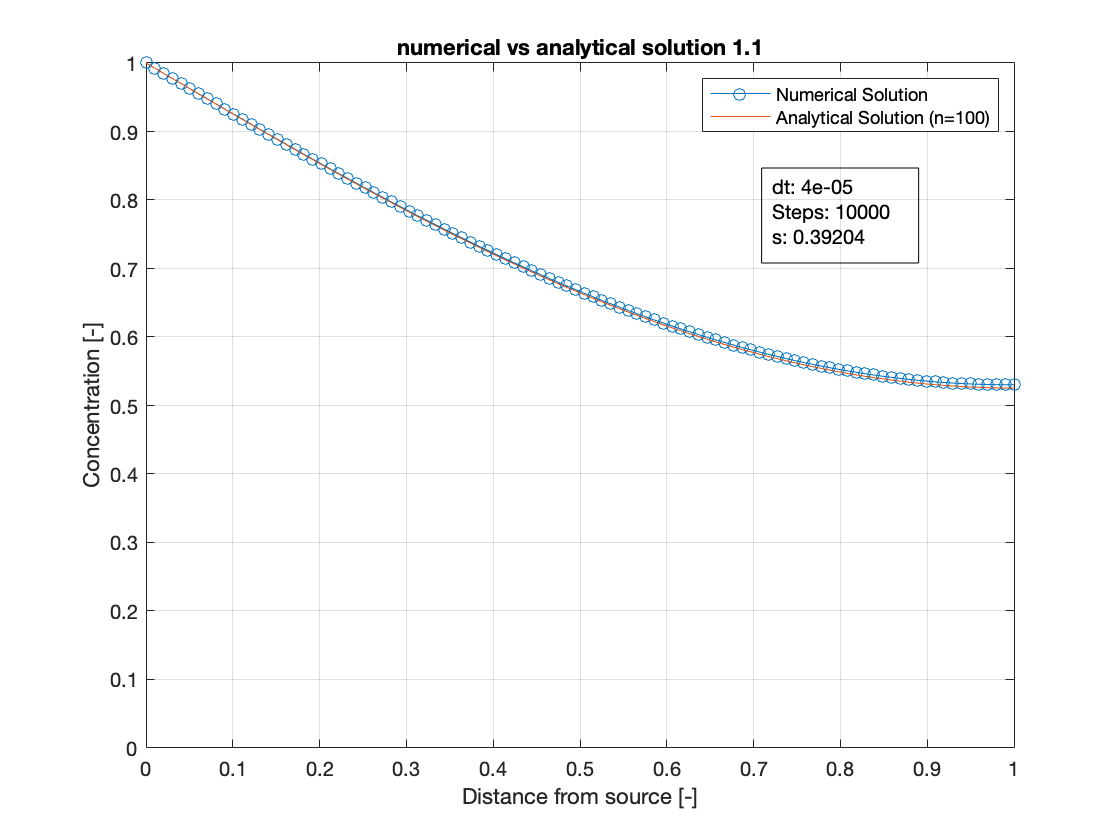


try
close(v);
end

% Plot final solution
C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params, C_analytic);

## Exercise 1.2

clear all;
clc;
close all;
% Setup parameters for Problem
sim_name = 'concentration_1_2';
h = 1;
N = 100;
dt = 0.00005;
numberSteps = 10000;
makeVideo = true;

dx = h/(N-1);
s = dt/dx^2;

% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
% Set boundary condition at x=0
C(1) = 1;
% Set boundary condition at x=h
%C(end) = 1;
if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

% SIMULATION
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_explicit(C,s,2);
    
    if makeVideo && mod(i,30)==0
        %C_analytic = analyticalSolution(N,100,i*dt);
        writeFrame(v, C, x, i, sim_params)%, C_analytic)
    end
    
end

try
    close(v);
end

% Plot final solution
%C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params)%, C_analytic);

## Exercise 1.3

clear all;
clc;
close all;

% Setup parameters for Problem
h = 5;
N = 100;
dt = 0.00005;
numberSteps = 10000;
makeVideo = false;

dx = 1/(N-1);
s = dt/dx^2;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
% C_check = zeros(N,1);
C(1) = 1;
% C_check(1) = 1;

if makeVideo
    v = VideoWriter('concentration_1_3');
    open(v);
end
% M = zeros(N);
% M(  1:1+N:N*N) = 1+2*s;
% M(N+1:1+N:N*N) = -s;
% M(  2:1+N:N*N-N) = -s;
% M(N-1,N-1) = 1+s;
% M(1,1) = 1;
% M(1,2) = 0;
% M = M(1:N-1,1:N-1);
for i = 1:numberSteps
    C = makeTimeStep_implicit(C,s);
%     C_check(1:end-1) = M\C_check(1:end-1);
%     C_check(end) = C_check(end-1);
    if makeVideo
        h = figure;
        set(h, 'Visible', 'off');
        plot(x, C, 'LineWidth', 2)
        grid on;
        title('numerical solution 1.3')
        xlabel('Distance from source [-]')
        ylabel('Concentration [-]')
        xlim([0 1])
        ylim([0 1])

        frame = getframe(gcf);
        writeVideo(v,frame);
        close;
    end
    
end

try
close(v);
end

figure
plot(x, C)
hold on;
% plot(x,C_check, 'o')
title('numerical solution 1.3')
xlabel('Distance from source [-]')
ylabel('Concentration [-]')
xlim([0 1])
ylim([0 1])

## Exercise 1.4

clear all;
clc;
close all;

h = 5;
N = 100;
dt = 0.00005;
numberSteps = 10000;
makeVideo = false;

dx = 1/(N-1);
s = dt/dx^2;

x = linspace(0,h,N);
C = zeros(1,N);
C_check = zeros(N,1);
C(1) = 1;
C_check(1) = 1;
if makeVideo
    v = VideoWriter('concentration_1_4');
    open(v);
end
M = zeros(N);
M(  1:1+N:N*N) = 1+2*s;
M(N+1:1+N:N*N) = -s;
M(  2:1+N:N*N-N) = -s;
M(N-1,N-1) = 1+s;
M(1,1) = 1;
M(1,2) = 0;
M = M(1:N-1,1:N-1);

for i = 1:numberSteps
    C = makeTimeStep_implicit_CrankNicolson(C,s);
    C_check_iminus1 = [C_check;0];
    C_check_iplus1 = [0;C_check];
    C_check = s*C_check_iminus1(1:end-1) + (1-2*s)*C_check + s*C_check_iplus1(2:end);
    C_check(1:end-1) = M\C_check(1:end-1);
    C_check(end) = C_check(end-1);
    if makeVideo
        h = figure;
        set(h, 'Visible', 'off');
        plot(x, C, 'LineWidth', 2)
        grid on;
        title('numerical solution 1.4')
        xlabel('Distance from source [-]')
        ylabel('Concentration [-]')
        xlim([0 1])
        ylim([0 1])

        frame = getframe(gcf);
        writeVideo(v,frame);
        close;
    end
    
end

try
close(v);
end

figure
plot(x, C)
hold on;
plot(x,C_check, 'o')
title('numerical solution 1.4')
xlabel('Distance from source [-]')
ylabel('Concentration [-]')
xlim([0 1])
ylim([0 1])

## Exercise 2.1

clear all;
clc;
close all;

h = 1;
N = 101;
dt = 0.01;
numberSteps = 10;
makeVideo = false;

dx = 1/(N-1);

x = linspace(0,h,N);
C = zeros(1,N);
for i = 0:1:100
    if (i > 10 & i < 30)
        C(i) = 1;
    end
end

if makeVideo
    v = VideoWriter('concentration_2_1_rectangle');
    open(v);
end

C0 = dt/dx;
for i = 1:numberSteps
    C = makeTimeStep_upwind(C,C0);
    
    if makeVideo
        h = figure;
        set(h, 'Visible', 'off');
        plot(x, C, 'LineWidth',2)
        grid on;
        title('numerical solution 2.1 Rectangle')
        xlabel('Distance [-]')
        ylabel('Concentration [-]')
        xlim([0 1])
        ylim([-2 2])

        frame = getframe(gcf);
        writeVideo(v,frame);
        close;
    end
    
end

try
close(v);
end

figure
plot(x, C, 'LineWidth',2)
grid on;
title('numerical solution 2.1')
xlabel('Distance [-]')
ylabel('Concentration [-]')
xlim([0 1])
ylim([-2 2])


%% part two

t = x;
C = exp(-10.*(4.*t-1).^2);

if makeVideo
    v = VideoWriter('concentration_2_1_gauss');
    open(v);
end

C0 = dt/dx;
for i = 1:numberSteps
    C = makeTimeStep_upwind(C,C0);
    
    if makeVideo
        h = figure;
        set(h, 'Visible', 'off');
        plot(x, C, 'LineWidth',2)
        grid on;
        title('numerical solution 2.1 Gauss')
        xlabel('Distance [-]')
        ylabel('Concentration [-]')
        xlim([0 1])
        ylim([-2 2])

        frame = getframe(gcf);
        writeVideo(v,frame);
        close;
    end
    
end

try
close(v);
end

figure
plot(x, C, 'LineWidth',2)
grid on;
title('numerical solution 2.1')
xlabel('Distance [-]')
ylabel('Concentration [-]')
xlim([0 1])
ylim([-2 2])